% parametros
clc
clear all
close all

g = 9.81;
prompt1 = 'Ángulo: '

prompt1 = 'Ángulo: '

angle = input(prompt1);
prompt2 = 'Altura inicial: '

prompt2 = 'Altura inicial: '

initial_height = input(prompt2);
prompt3 = 'Velocidad inicial: '

prompt3 = 'Velocidad inicial: '

initial_velocity = input(prompt3);
air_resistance = 0.02;

initial_x = 0;
initial_y = initial_height;
v0x = initial_velocity * cosd(angle);
v0y = initial_velocity * sind(angle);

x = initial_x;
y = initial_y;
vx = v0x;
vy = v0y;
t = 0;
time_step = 0.01;
x_data = [];
y_data = [];

while y >= 0
    x_data = [x_data, x];
    y_data = [y_data, y];
    ax = -air_resistance * vx;
    ay = -g -air_resistance *vy;
    vx = vx + ax * time_step;
    vy = vy + ay * time_step;
    x = x + vx * time_step;
    y = y + vy * time_step;
    t = t + time_step;
end

Invalid expression. When calling a function or indexing a variable, use parentheses. Otherwise, check for mismatched delimiters.

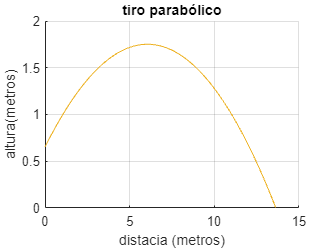


% gráfica con rozamiento
figure;
hold on
for i = 1:length(x_data)
    plot(x_data(1:i), y_data(1:i));
    xlabel('distacia (metros)');
    ylabel('altura(metros)');
    title('tiro parabólico')
    grid on;
    pause(0.1);
end


fprintf('Tiempo de vuelo con rozamiento: %.2f segundos\n', t);

Tiempo de vuelo con rozamiento: 1.08 segundos


fprintf('Distancia recorrida con rozamiento: %.2f metros\n', max(x_data));

Distancia recorrida con rozamiento: 13.62 metros


fprintf('Altura máxima con rozamiento: %.2f metros\n', max(y_data));

Altura máxima con rozamiento: 1.75 metros
